# Passive Dynamic Walker Simulation

clear;clc;

pdw.l1 = 2; pdw.l2 = 2;
pdw.m1 = 0.5; pdw.m2 = 0.5; pdw.mh = 0.5;

pdw.gamma = pi/30;
fps = 20;
deltat = 2;
L = 10;
x = 1.5; 
y = (L-x)*tan(pdw.gamma);

% Here q = [th1 th2 th1d th2d];
% Requires manual tuning to make the PDW walk on the ramp. Needs some intuition
q0 = [0.15;-0.30;-1.2;2.4];

## Poincare Map Fixed Point

options = optimset('TolFun',1e-12,'TolX',1e-12,'MaxIter',700,'MaxFunEvals',700,'Display','off');
[qfixed,val,flag] = fsolve(@(qfixed) qfixed - poincare_map(qfixed,deltat,pdw),q0,options);
if flag == 1
    disp('Successfully Converged.');
    q0 = qfixed;
else
    disp('Failed to converge. Modify, IC or PDW parameters.')
end

Successfully Converged.


## Fixed Point Stability

% Jacobian using central difference
% ptrb = 1e-6;
% Jqstar = zeros(length(qfixed));
% for n=1:length(qfixed)
%     qleft = qfixed; qright = qfixed;
%     qleft(n) = qleft(n) - ptrb; qright(n) = qright(n) + ptrb;   
%     Jqstar(:,n) = poincare_map(qright,deltat,pdw) - poincare_map(qleft,deltat,pdw);
% end
% Jqstar = Jqstar / (2*ptrb);

poincare_map_ = @(q) poincare_map(q,deltat,pdw);
Jqstar = jacobianest(poincare_map_,qfixed)

Jqstar =    3.652715418138042  -1.232859127276121   1.919725819972889   0.088956004105809
  -7.305430836304520   2.465718254651409  -3.839451639946478  -0.177912008211608
   3.065453495759895  -0.701200385201016   1.639736221803902  -0.000424159041424
  11.314444107223299  -3.659409087128889   5.865506777275724   0.309880552155772


abs(eig(Jqstar))

ans =    7.785959629183683
   0.248869722445979
   0.000000000046068
   0.033221095165527


abs(det(Jqstar))

ans =      2.965463014448221e-12


## Integrate

n = 6; % Number of steps
tstart = 0;
tsim = [];
qsim = [];
foot_anchor_temp = [x;y];

for k = 1:n
    [t,q,q0next] = one_step(tstart,deltat,q0,pdw);
    tq = linspace(t(1),t(end),fps)';
    qq(:,1) = interp1(t,q(:,1),tq);
    qq(:,2) = interp1(t,q(:,2),tq);
    qq(:,3) = interp1(t,q(:,3),tq);
    qq(:,4) = interp1(t,q(:,4),tq);
    tsim = [tsim; tq(1:end-1,:)];
    qsim = [qsim; qq(1:end-1,:)];
    th1 = q(end,1); th2 = q(end,2);
    new_anchor = [foot_anchor_temp(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + pdw.l2*(cos(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + sin(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))); ... 
        foot_anchor_temp(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - pdw.l2*(cos(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - sin(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)))];
    foot_anchor_temp = [foot_anchor_temp new_anchor];
    q0 = q0next;
    tstart = t(end);
end

stack_size = length(tsim)/n;
foot_anchor = [];
color_switch = 1;
for k=1:size(foot_anchor_temp,2)-1
    foot_anchor = [foot_anchor repmat([foot_anchor_temp(:,k);color_switch],1,stack_size)];
    color_switch = -color_switch;
end

## Animate

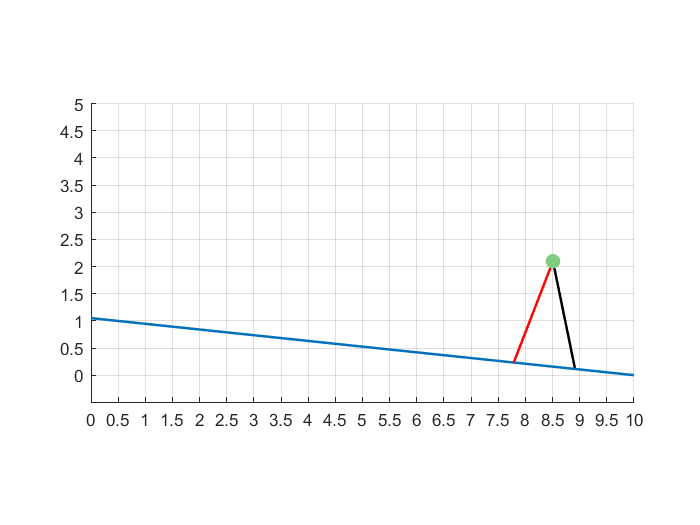

figure(1);
for k=1:length(tsim)
    th1 = qsim(k,1); th2 = qsim(k,2);
    Ggh = [foot_anchor(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)); ...
        foot_anchor(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))];
    GgC2 = [foot_anchor(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + pdw.l2*(cos(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + sin(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))); ... 
        foot_anchor(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - pdw.l2*(cos(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - sin(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)))];
    
    if foot_anchor(3,k) > 0
        leg1_color = 'black';
        leg2_color = 'red';
    else
        leg1_color = 'red';
        leg2_color = 'black';
    end
    
    grid on;
    hold on;
    line([0 L],[L*tan(pdw.gamma) 0],'LineWidth',1.5); % Ramp
    h1 = line([foot_anchor(1,k) Ggh(1)],[foot_anchor(2,k) Ggh(2)],'LineWidth',1.5,'Color',leg1_color); % Stance Leg
    h2 = line([Ggh(1) GgC2(1)],[Ggh(2) GgC2(2)],'LineWidth',1.5,'Color',leg2_color); % Swing Leg
    h3 = plot(Ggh(1),Ggh(2),'.','MarkerSize',30,'Color',[0.5 0.8 0.5]); % Hip
    axis([0 L -0.5 L/2]);
    xticks(0:0.5:L);
    yticks(0:0.5:L);
    daspect([1 1 1]);
    drawnow;
    
    % pause(0.5);
    if k ~= length(tsim)
        delete(h1);
        delete(h2);
        delete(h3);
    end    
end

## Plot Angles and Angular Velocity

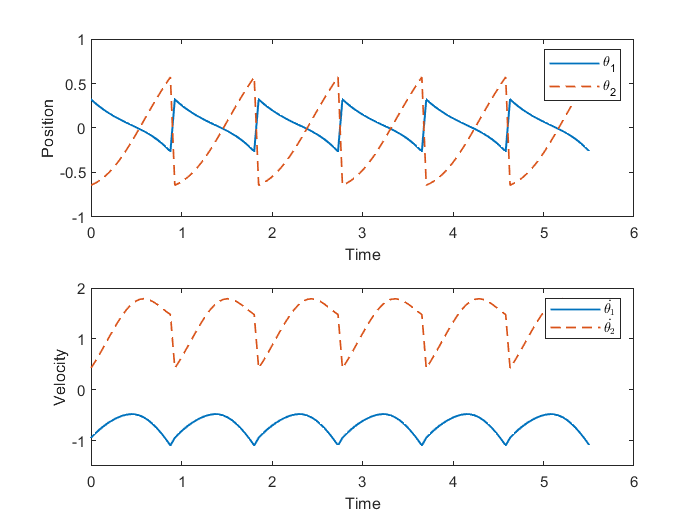

figure(2);
subplot(2,1,1);
plot(tsim,qsim(:,1),'LineWidth',1);
hold on;
plot(tsim,qsim(:,2),'--','LineWidth',1);
ylabel('Position');
xlabel('Time');
axis([0 6 -1 1]);
legend('\theta_1','\theta_2');
subplot(2,1,2);
plot(tsim,qsim(:,3),'LineWidth',1);
hold on;
plot(tsim,qsim(:,4),'--','LineWidth',1);
ylabel('Velocity');
xlabel('Time');
axis([0 6 -1.5 2]);
legend({'$\dot{\theta_1}$', '$\dot{\theta_2}$'}, 'Interpreter', 'latex');